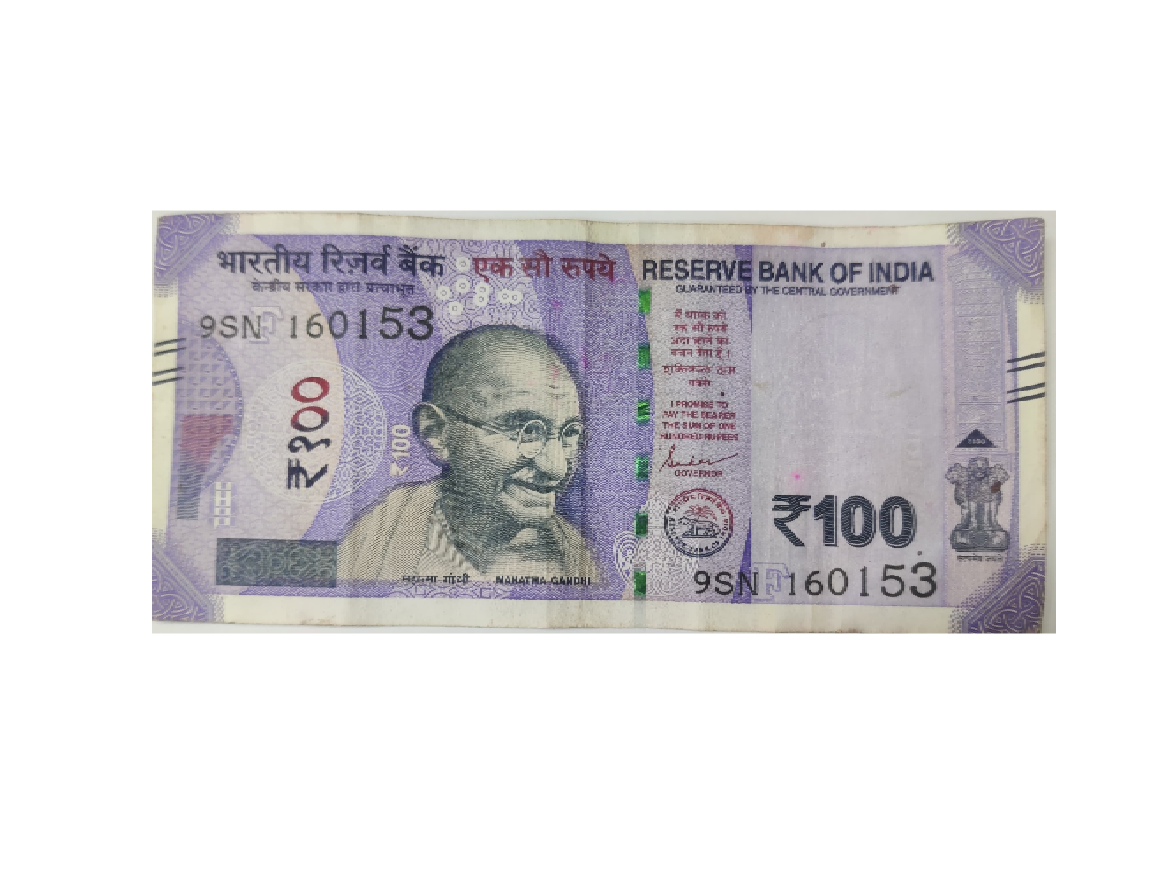

image=imread('100_note.jpeg');
imshow(image)

greyimg=rgb2gray(image)

greyimg = 1580x3378 uint8 matrix
   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   218   218   218   218   218   218   218   218   217   217   217   217   217   217   217   217   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216
   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   218   218   218   218   218   218   218   218   217   217   217   217   217   217   217   217   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216
   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   219   218   218   218   218   218   218   218   218   217   217   217   217   217   217   217   217   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216   216
   219   219   219   219   219   219   219   219   219   219   2

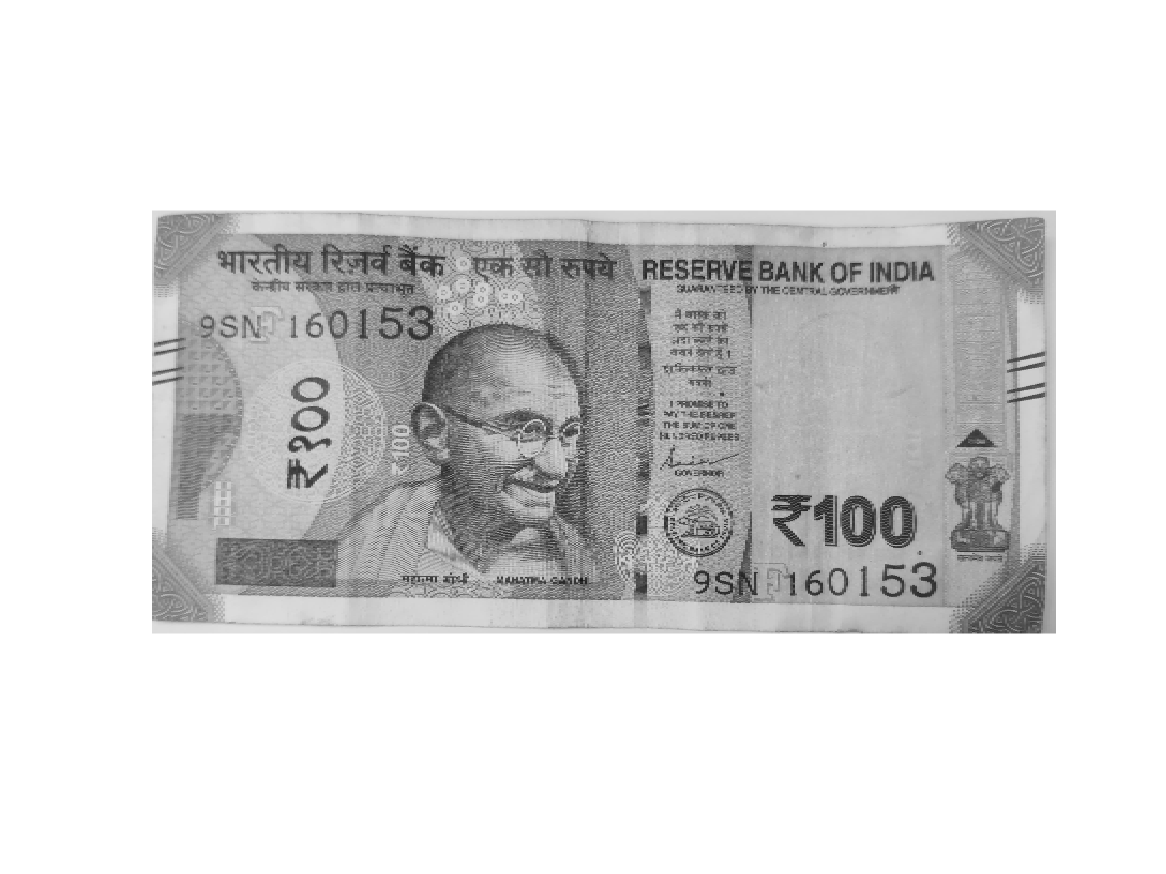


imshow(greyimg);

geeyimg=histeq(greyimg)

geeyimg = 1580x3378 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   2

imshow(greyimg)

% Get the size of the image
[rows, cols] = size(greyimg)

rows = 1580

cols = 3378

% Preallocate a 3D array to store the bit planes
bitPlanes = zeros(rows, cols, 8, 'uint8')

bitPlanes = 1580x3378x8 uint8 array
bitPlanes(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

% Extract each bit plane
for bit = 0:7
    % Use bitget to extract the bit plane
    bitPlanes(:, :, bit+1) = bitget(greyimg, bit+1);
end

jvhhj

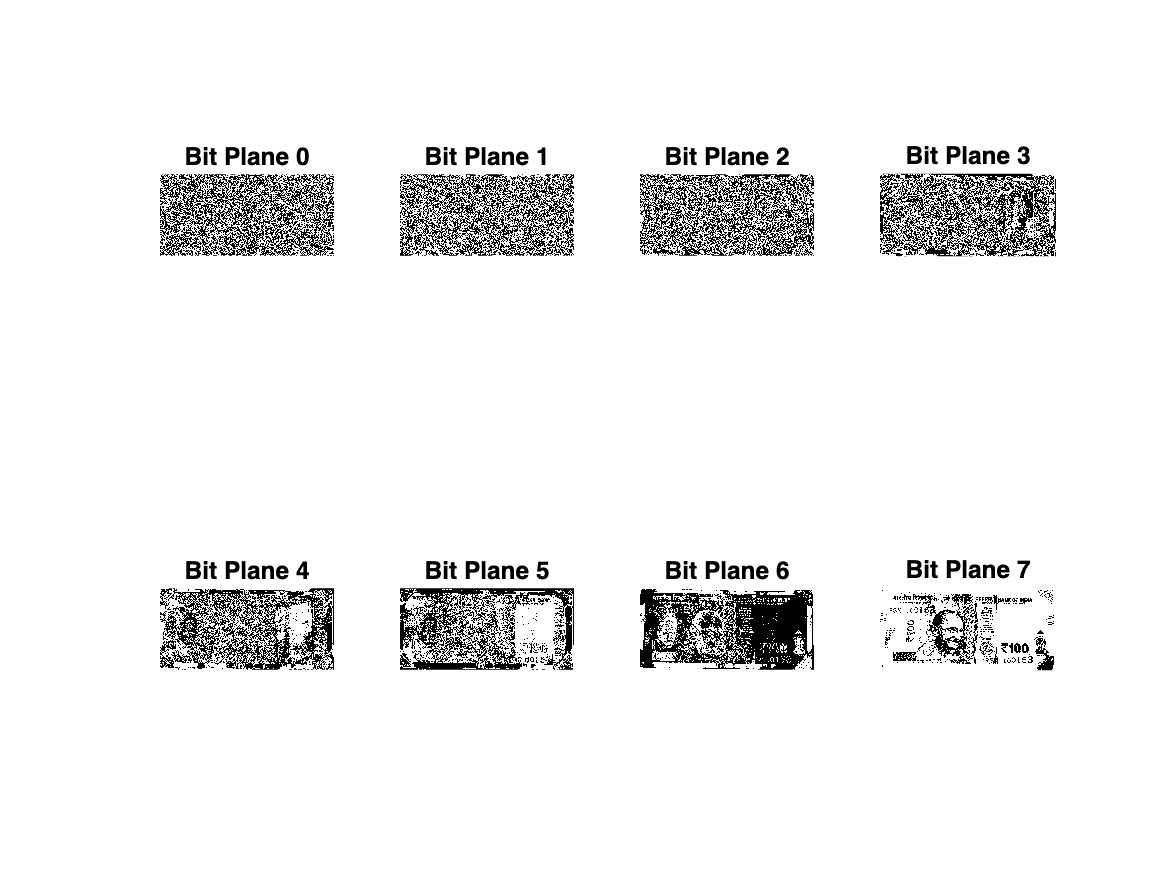

% Display the bit planes
figure;
for bit = 0:7
    subplot(2, 4, bit+1);
    imshow(bitPlanes(:, :, bit+1) * 255); % Multiply by 255 for visualization
    title(['Bit Plane ', num2str(bit)]);
end

% Display the matrices for each bit plane in the Command Window
for bit = 0:7
    fprintf('Bit Plane %d Matrix:\n', bit);
    disp(bitPlanes(:, :, bit+1)); % Display the matrix for the bit plane
end

Bit Plane 0 Matrix:


   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   0   1   1   0   0   1   1   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   0   0   1   0   0   0   0   0   0   0   0   1   1   0   0   1   1   0   0   1   1   1   1   1   1   1   1   0   1   1   1   0   1   1   1   0   1   1   0   1   0   1   1   1   0   0   1   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   1   1   0   0   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   1   1   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0

Bit Plane 1 Matrix:


   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   1   1   1   1   1   0   0   1   1   1   0   1   0   0   0   1   0   1   0   0   0   0   0   0   0   0   1   0   1   1   1   1   0   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   0   0

Bit Plane 2 Matrix:


   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   0   0   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   1   1

Bit Plane 3 Matrix:


   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0

Bit Plane 4 Matrix:


   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1

Bit Plane 5 Matrix:


   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

Bit Plane 6 Matrix:


   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

Bit Plane 7 Matrix:


   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

set bit 0 valus to zero and adding again

% Set Bit Plane 0 to 0
bitPlanes(:, :, 1) = 0; % Modify Bit Plane 0

showing image

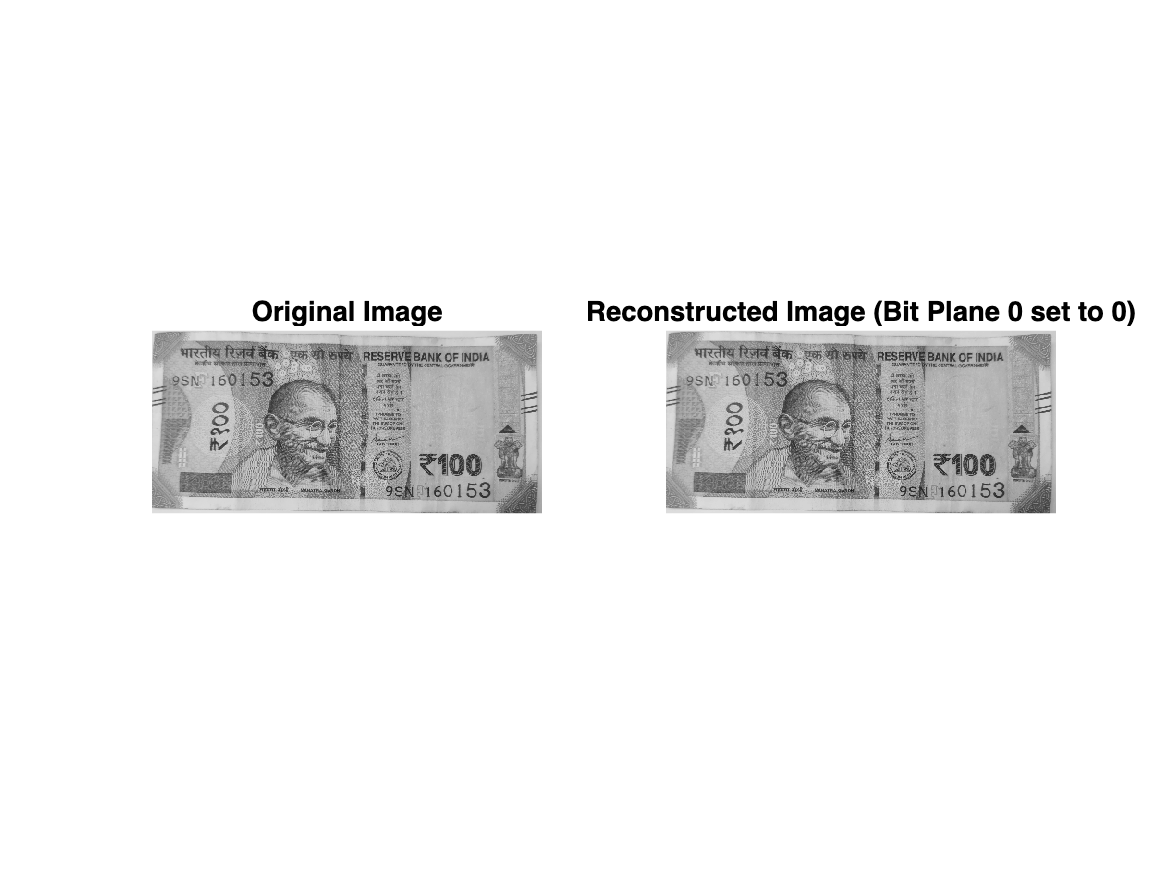

% Reconstruct the image by combining all bit planes
reconstructedImage = zeros(rows, cols, 'uint8');
for bit = 0:7
    reconstructedImage = reconstructedImage + bitPlanes(:, :, bit+1) * 2^bit;
end

% Display the original and reconstructed images
figure;
subplot(1, 2, 1);
imshow(greyimg);
title('Original Image');

subplot(1, 2, 2);
imshow(reconstructedImage);
title('Reconstructed Image (Bit Plane 0 set to 0)');